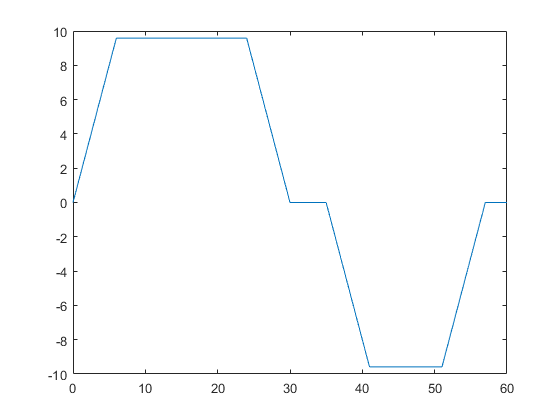

t = 0:0.01:60;
v=zeros(length(t),1); 
v(t<6)=1.6*t(t<6);   
v(t>24 & t<=30)=flip(v(t<6));
nagib = flip(v(t<6));
v(t>=6 & t<=24)=max(v);
v(t>30 & t<35)=0;
v(t>=35 & t<41)=-1.6*t(t<6);
v(t>=41 & t<=51)=-max(v);
v(t>51 & t<=57)=-nagib;
plot(t,v);

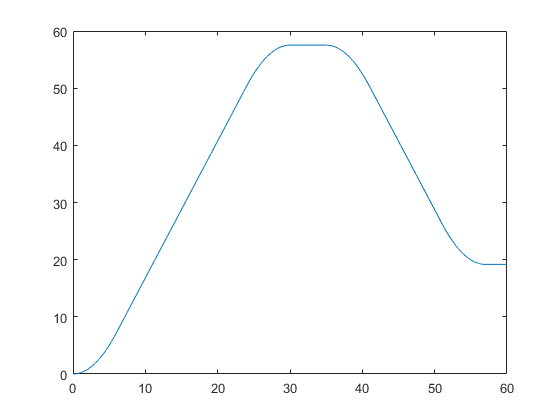

akc=gradient(v,t);

r=zeros(length(t),1);
r0=0;
v0=0;
a0=0;
for i=1:length(t)-1
r(i) = r0 + (v0+v(i+1)-v(i))*(t(i+1)-t(i)) + 0.5*akc(i)*(t(i+1)-t(i))^2;
r0=r(i);
v0=v(i);
end
r(end)=r(6000);
plot(t,r*0.25)

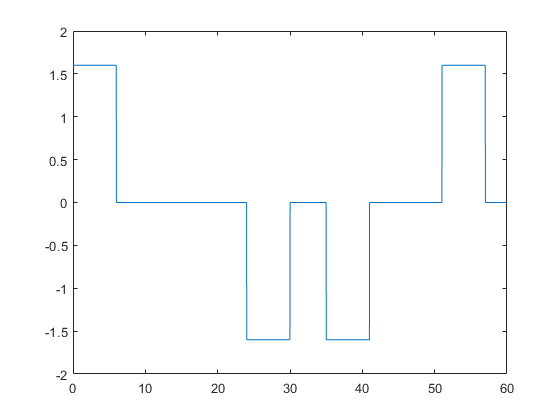

plot(t,akc)